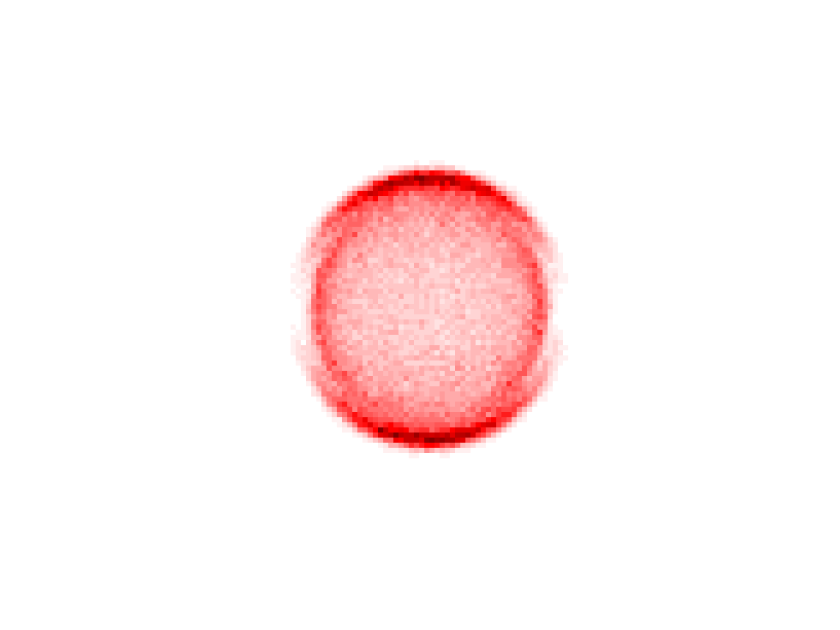

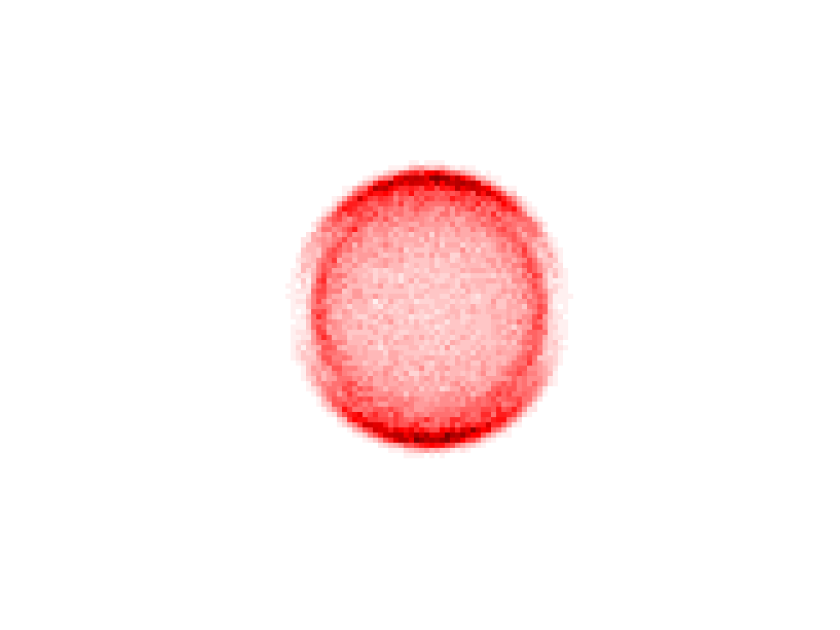

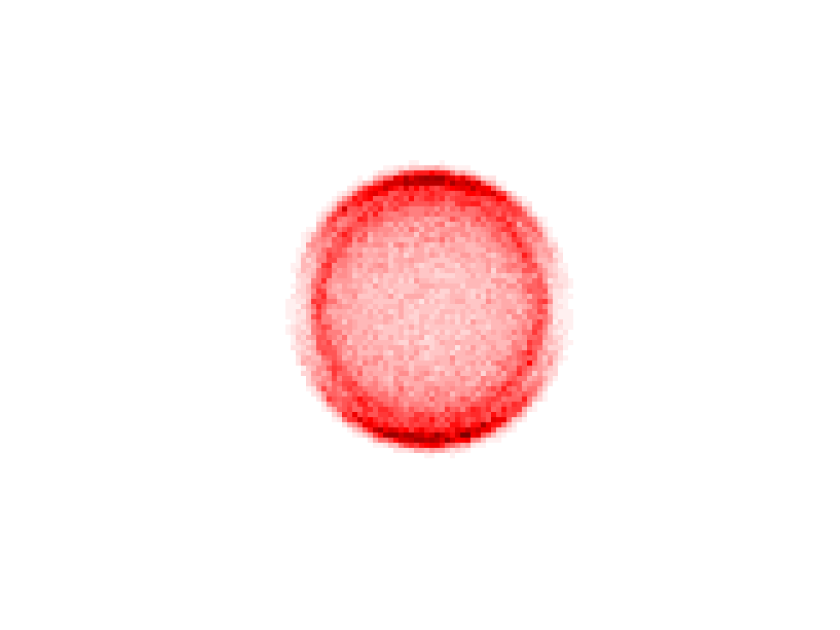

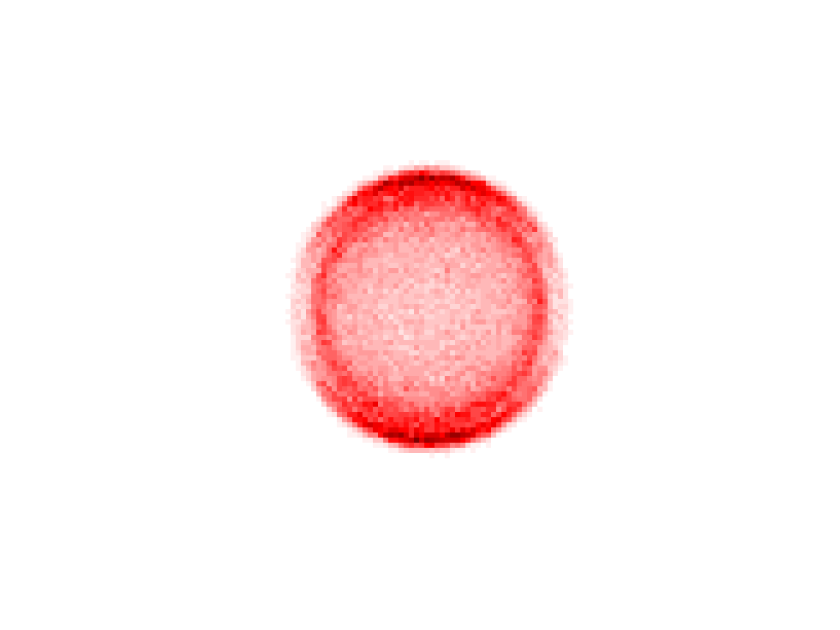

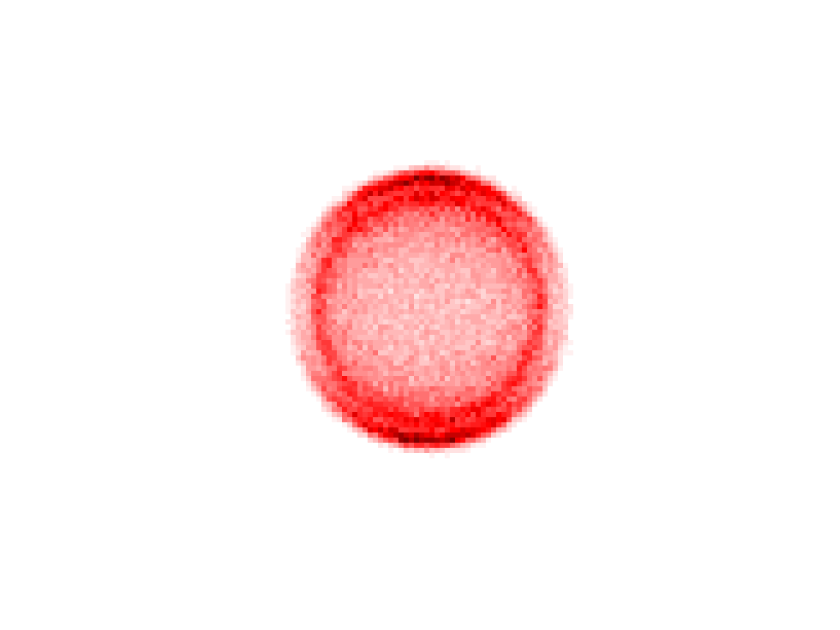

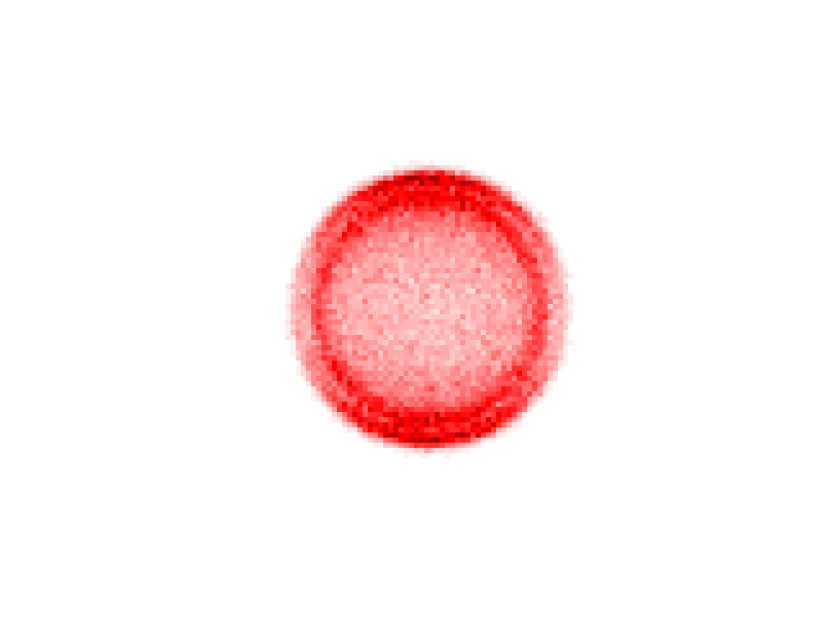

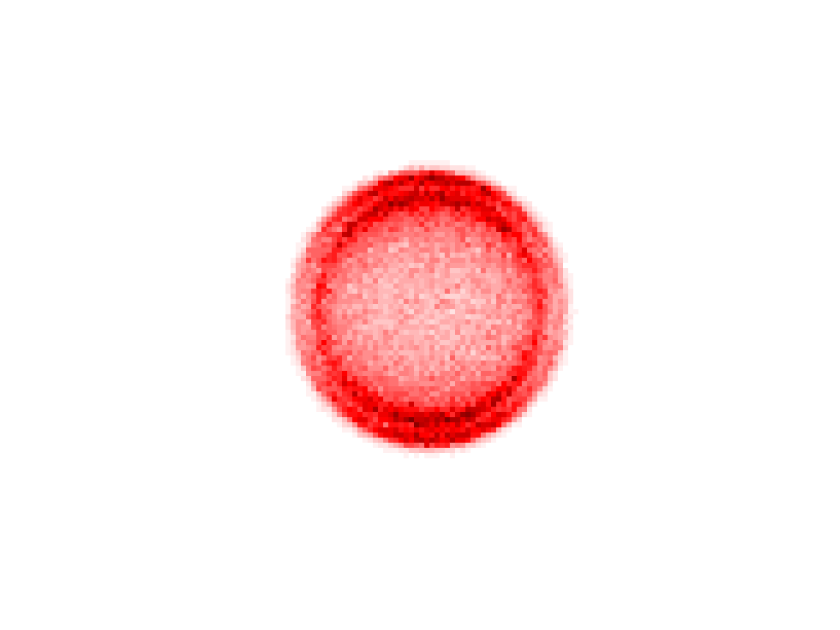

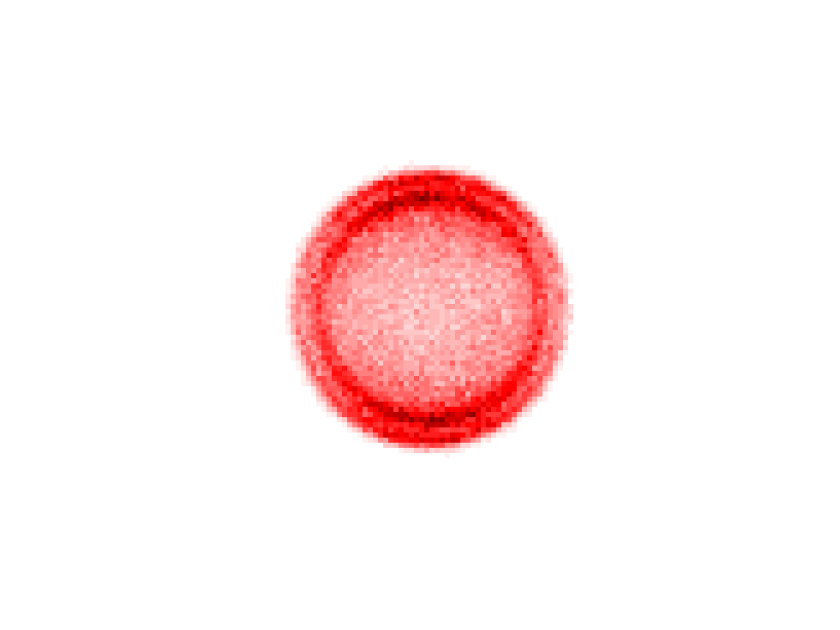

% This code produces a dataset consisting of images with two rings. In each image, the 
% anisotropy parameter (beta2) of the outer (inner) ring starts at 2 (-1), which are 
% changed by either +/- 0.2 until they switch to 2 (outer) and -1 (inner). 

% see "assess_after_process_differentb2.mlx" for how these images were
% analysed after being processed through the network

% MPhys Research Project 2022/23
% Ross Anderson (H00295702)



% clear commands
clc
clear
close all


% set up coordinate system
x_res = 96;
y_res = 96;
x = linspace(-1, 1, x_res);
y = linspace(-1, 1, y_res);
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);

cos_theta = Y./R;

P2 = (1/2)*(3*cos_theta.^2 - 1);    %second legendre polynomial

% set a threshold to discard the image if the intensity is greater than
% this value at the edges
threshold = 0.01;

% number of images to produce
N = 16;

coeffs.threshold_for_discard = threshold;
coeffs.number_of_images = N;

ring1 = cell(1, N);
ring1{1, N} = [];

ring2 = cell(1, N);
ring2{1, N} = [];
 
% initialise the increment (first image should not be altered)
b2_inc = 0;

images = cell(1, N);
images{1, N} = [];

images_sampled = cell(1, N);
images_sampled{1, N} = [];

images_gaussfilt = cell(1, N);
images_gaussfilt{1, N} = [];


for i = 1:N
    check = 0;
    while check == 0

        % generate ring 1
        W1 = 0.03; 
        R1 = 0.55;
        A1 = 1;
        B21 = 2 - b2_inc;
        I1 = A1*exp(-((R-R1)/W1).^2).*(1 + B21*P2);
        I1 = Abel(I1);

        % generate ring 2
        W2 = 0.03;
        R2 = R1 - 0.08;
        A2 = 1;
        B22 = -1 + b2_inc;
        I2 = A2*exp(-((R-R2)/W2).^2).*(1 + B22*P2);
        I2 = Abel(I2);

        ring1{i} = I1;
        coeffs_ring1.W0(i) = W1;
        coeffs_ring1.R0(i) = R1;
        coeffs_ring1.B2(i) = B21;
        coeffs_ring1.A0(i) = A1;

        ring2{i} = I2;
        coeffs_ring2.W0(i) = W2;
        coeffs_ring2.R0(i) = R2;
        coeffs_ring2.B2(i) = B22;
        coeffs_ring2.A0(i) = A2;

        I_comb_check = I1 + I2;
        I_comb_check = I_comb_check/max(I_comb_check, [], 'all');

        if any(I_comb_check(1,:) > threshold) || any(I_comb_check(:,1) > threshold) || any(I_comb_check(end,:) > threshold) || any(I_comb_check(:,end) > threshold)
            check = 0;
        else
            check = 1;
        end

    end

    I_combined = I1 + I2;
    I_combined = rescale(I_combined);
    %     showim(I_combined, 1)
    I_combined = I_combined/sum(I_combined, 'all');
    counts = I_combined*10^5;
    I_sampled = poissrnd(counts, height(I_combined), length(I_combined));
    if sum(isnan(I_sampled)) > 0
        I_sampled = images_sampled{i - 1};
    end
    %     showim(I_sampled, 1)
    %     shading flat
    counts_in_image = sum(I_sampled,'all');
    coeffs.counts(i) = counts_in_image;
    I_gaussfilt = imgaussfilt(I_sampled, 1);    
    %     showim(I_gaussfilt, 1)
    %     shading flat
    I_combined = I_combined/max(I_combined, [], 'all');
    I_sampled = I_sampled/max(I_sampled, [], 'all');
    I_gaussfilt = I_gaussfilt/max(I_gaussfilt, [], 'all');
    images{i} = I_combined;
    images_sampled{i} = I_sampled;
    images_gaussfilt{i} = I_gaussfilt;

    b2_inc = b2_inc + 0.2;
end

images_mat = cell2mat(reshape(images, 1, 1, []));
images_sampled_mat_full = cell2mat(reshape(images_sampled, 1, 1, []));
images_gaussfilt_mat_full = cell2mat(reshape(images_gaussfilt, 1, 1, []));

images_sampled_mat = images_sampled_mat_full((x_res/2+1):end, (x_res/2+1):end, :);
images_gaussfilt_mat = images_gaussfilt_mat_full((x_res/2+1):end, (x_res/2+1):end, :);


coeffs.ring1 = coeffs_ring1;
coeffs.ring2 = coeffs_ring2;

save("centroid_process", "images_sampled_mat")
save("gaussfilt_process", "images_gaussfilt_mat")
save("images", "images_mat")
save("coeffs_process", "coeffs")


for u = 1:16

    showim(images_sampled_mat_full(:, :, u), 1)
    shading flat
%     showim(images_gaussfilt_mat_full(:, :, u), 1)
%     shading flat

end